# Power-Split HEV Model

## HEV System Model Overview

Power-split HEV is a series-parallel hybrid system and has a planetary gear to split the power from a combustion engine to driving the axle and generating the electrical power. The picture below is a high-level schematic of the power-split drive unit where the motor-generator 1 (MG1) and the engine are connected to the planetary gear, and the MG2 and the planetary gear are linked via a reduction gear which is connected to the axle.

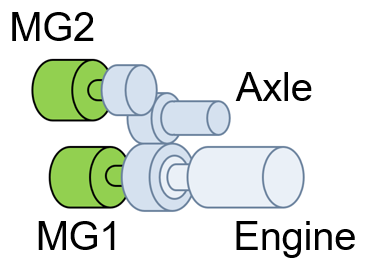

Power-Split Drive Unit

**PowerSplitHEV_system_model** represents a longitudinal vehicle model with the engine power-split hybrid electric drive system. The model is suitable for vehicle system-level analysis such as energy efficiency in various drive cycles.

Click the button below to open the HEV model.

 
open_system("PowerSplitHEV_system_model")

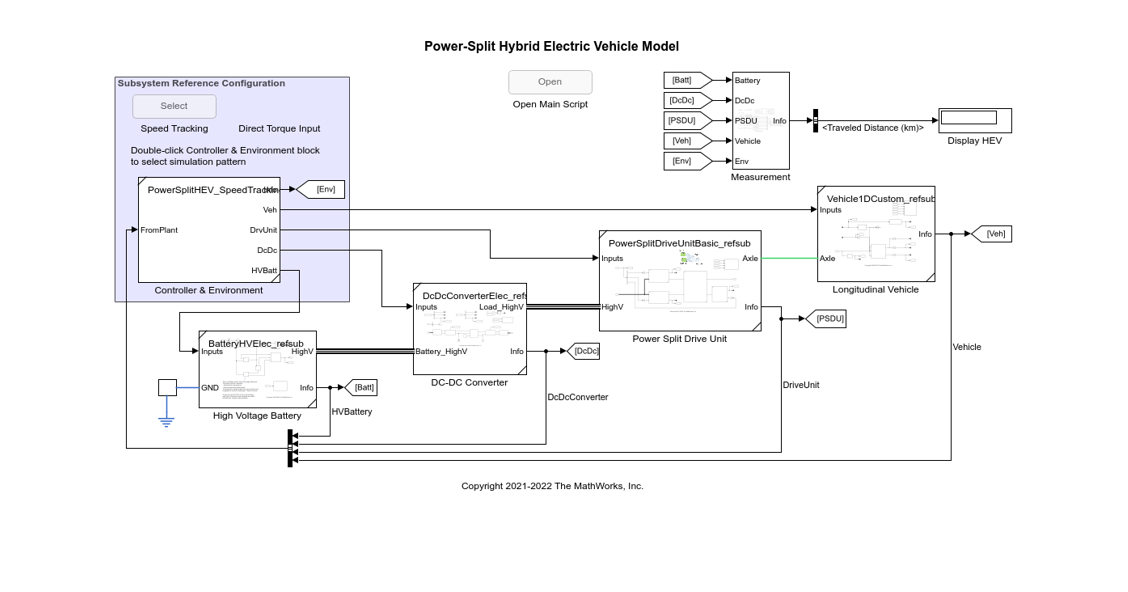

screenshotSimulink( ...
  "SimulinkModelName", "PowerSplitHEV_system_model", ...
  "SaveFolder", currentProject().RootFolder + "/utils", ...
  "OutputImageWidth_px", 900 );
img = imread(currentProject().RootFolder + "/utils/image_PowerSplitHEV_system_model.png");
imshow(img)

## Plant Parameters

Click the button below to open the script defining parameters for the plant.

 
edit("PowerSplitHEV_params.m")

## Controller Parameters

Click the button below to open the script defining parameters for the controller.

 
edit("HEVPowerSplitControl_params.m")

Two types of controllers are available. One is **speed tracking** controller which takes vehicle speed reference as input and control drive unit so that the vehicle tracks the reference speed. Use this controller for dricve cycle simulation. The other is a **direct torque input** source which takes torque commands to an engine and motors as input and simply send them to the drive unit. Use this to examine system behaviors for predefined torque command sequences. These controllers are available as referenced subsystems. You can use one of them as the Controller & Environment block in the system model.

## Speed Tracking Simulation

Click the button below to open the main script for speed tracking simulation.

 
edit("PowerSplitHEV_SpeedTracking_main_script.mlx")

## Direct Torque Input Simulation

Click the button below to open the main script for direct torque input simulation.

 
edit("PowerSplitHEV_DirectInput_main_script.mlx")

## Workflows

### Parameter Sweep Workflow for Electrical Efficiency Analysis

Investigate the impact of the reduction gear ratio and the capacity and weight of high-voltage battery on the vehicle electrical efficiency. Click the button below to open the workflow script.

 
edit("PowerSplitHEV_SpeedTracking_sweep.mlx")

## Customize Default Simulation Pattern

You can change the default external input signals. Click the button below to open the set up script where the default signals are loaded.

 
edit("PowerSplitHEV_system_model_setup.m")

*Copyright 2022 The MathWorks, Inc.*